t = 0:0.01:10-0.01;
tau = 0.01;
N = 10/tau;
y = exp(-2*abs((t-5)));
w = -pi/tau + (0:N-1)*2*pi/(N*tau);%4.2d
Y_temp = tau*fft(y);

Xa = 1./(2+1j.*w) + 1./(2-1j.*w);
Ya = exp(-1j.*5*w).*Xa;%4.2b

Y = fftshift(tau*fft(y))

Y =    0.0001 + 0.0000i  -0.0001 - 0.0000i   0.0001 - 0.0000i  -0.0001 + 0.0000i   0.0001 - 0.0000i  -0.0001 + 0.0000i   0.0001 - 0.0000i  -0.0001 + 0.0000i   0.0001 - 0.0000i  -0.0001 + 0.0000i   0.0001 - 0.0000i  -0.0001 + 0.0000i   0.0001 - 0.0000i  -0.0001 + 0.0000i   0.0001 - 0.0000i  -0.0001 + 0.0000i   0.0001 - 0.0000i  -0.0001 + 0.0000i   0.0001 - 0.0000i  -0.0001 + 0.0000i   0.0001 + 0.0000i  -0.0001 - 0.0000i   0.0001 + 0.0000i  -0.0001 - 0.0000i   0.0001 + 0.0000i  -0.0001 - 0.0000i   0.0001 + 0.0000i  -0.0001 - 0.0000i   0.0001 + 0.0000i  -0.0001 - 0.0000i   0.0001 + 0.0000i  -0.0001 - 0.0000i   0.0001 + 0.0000i  -0.0001 - 0.0000i   0.0001 + 0.0000i  -0.0001 - 0.0000i   0.0001 + 0.0000i  -0.0001 - 0.0000i   0.0001 + 0.0000i  -0.0001 - 0.0000i   0.0001 + 0.0000i  -0.0001 - 0.0000i   0.0001 + 0.0000i  -0.0001 - 0.0000i   0.0001 + 0.0000i  -0.0001 - 0.0000i   0.0001 + 0.0000i  -0.0001 - 0.0000i   0.0001 + 0.0000i  -0.0001 - 0.0000i


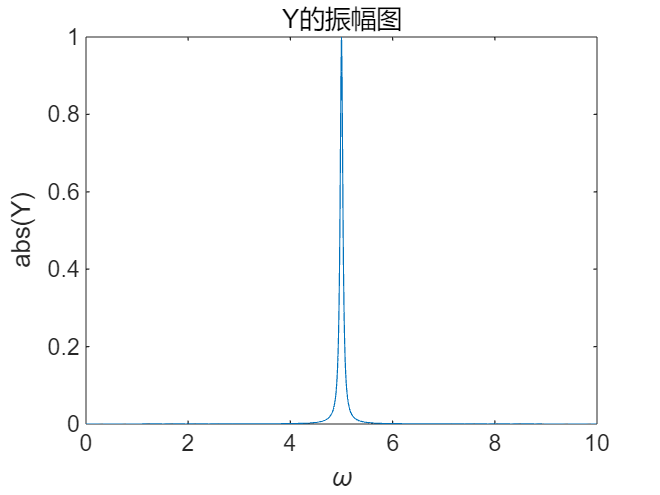

figure
plot(t,abs(Y));
title('Y amplitude figure'),
xlabel('\omega'),
ylabel('abs(Y)');%4,2c

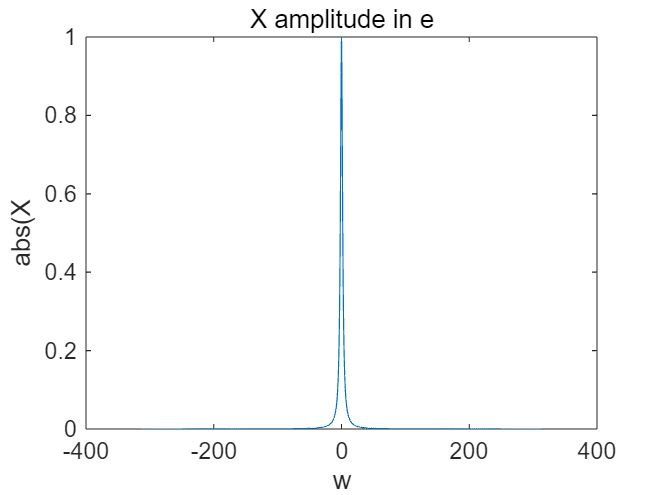


X = Y.*exp(1j.*5*w);
plot(w,abs(X));
title('X amplitude in e'),
xlabel('w'),
ylabel('abs(X');%4.2e

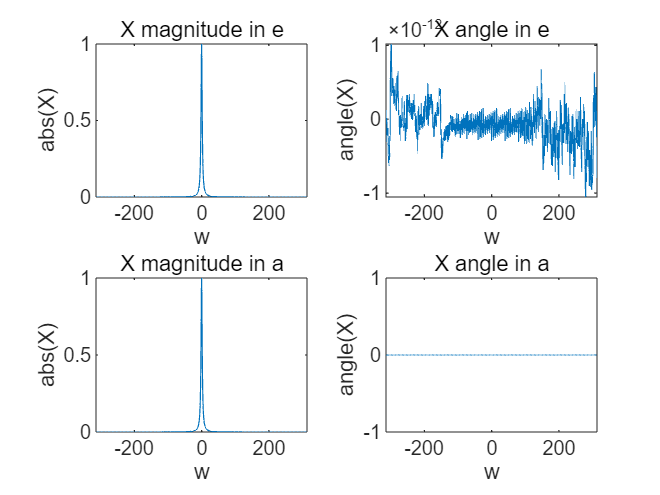


figure
subplot(2,2,1),
plot(w,abs(X));
title('X magnitude in e'),
xlabel('w'),
ylabel('abs(X)');
subplot(2,2,2),
plot(w,angle(X));
title('X angle in e'),
xlabel('w'),
ylabel('angle(X)');
X1 = 1./(2+1j.*w) + 1./(2-1j.*w);
subplot(2,2,3),
plot(w,abs(X1));
title('X magnitude in a'),
xlabel('w'),
ylabel('abs(X)');
subplot(2,2,4),
plot(w,angle(X1));
title('X angle in a'),
xlabel('w'),
ylabel('angle(X)');

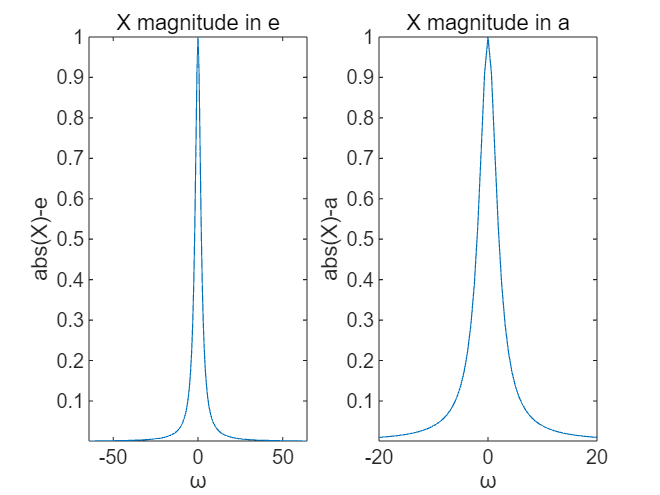


figure
subplot(1,2,1)
plot(w,abs(X))
title('X magnitude in e')
ylabel('abs(X)-e')
xlabel('ω')
ylim([0.001,1])
subplot(1,2,2)
plot(w,abs(X1))
title('X magnitude in a')
ylabel('abs(X)-a')
xlabel('ω')
xlim([-20,20])
ylim([0.001,1])

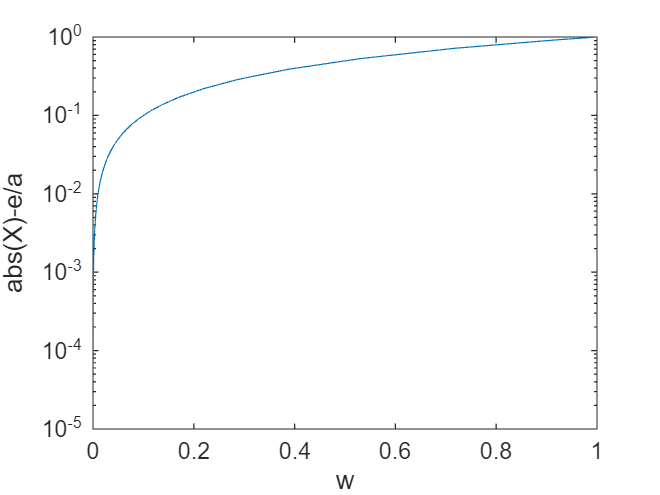


figure
semilogy(abs(X),abs(X1))
xlabel('w'),
ylabel('abs(X)-e/a')%4.2f

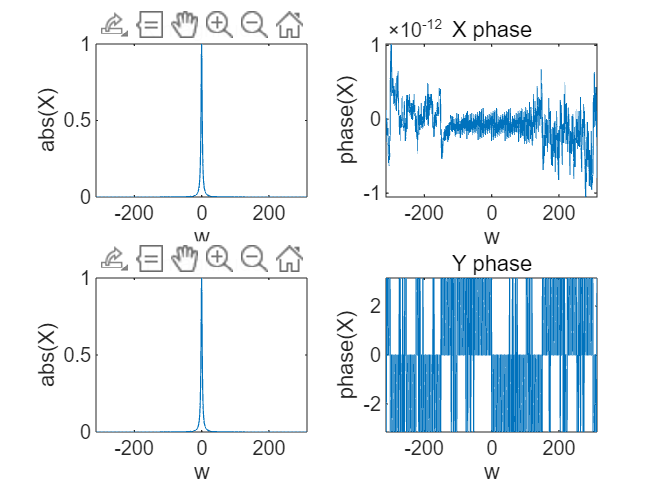


figure
subplot(2,2,1),
plot(w,abs(X));
title('X magnitude'),
xlabel('w'),
ylabel('abs(X)');
subplot(2,2,2),
plot(w,angle(X));
title('X phase'),
xlabel('w'),
ylabel('phase(X)');

subplot(2,2,3),
plot(w,abs(Y));
title('Y magnitude'),
xlabel('w'),
ylabel('abs(X)');
subplot(2,2,4),
plot(w,angle(Y));
title('Y phase'),
xlabel('w'),
ylabel('phase(X)');